## **Defining the parameter**

m_pendulum = 13/1000 ; %the mass of pendulum in gram

r = 50/1000 ; %length of arm in mm

l = (10/1000)/2; %length of arm of pendulum in mm

J_arm= 10.771075439837363 ; % J equivilant inertia for the arm from motor_j=parameter estimation

motor_j=J_arm;
motor_b=0.523596450597066 ; %damping equivlant measured from parameter estimation 
motor_k=1.149300000000000;
motor_l=2.357399939121937;
motor_r=0.136144129960745;
% Defining some constant for the system for sake of simplifing 
a=J_arm+(m_pendulum*r*r)

a = 10.7711


b=m_pendulum*l*r

b = 3.2500e-06

c=(4/3)*m_pendulum*l*l

c = 4.3333e-07

d=m_pendulum*9.8*l

d = 6.3700e-04

e=(a*c)-(b*b)

e = 4.6675e-06

% Defining motor parametr
motor_effeciency = 0.69

motor_effeciency = 0.6900

gear_box_effeciency = 0.9

gear_box_effeciency = 0.9000

gear_box_ratio = 1 % motor -> load 

gear_box_ratio = 1

G = ((motor_effeciency*gear_box_effeciency*motor_k*motor_k*(gear_box_ratio*gear_box_ratio))-(motor_b*motor_r))/(motor_r)

G = 5.5014

H= (motor_effeciency*gear_box_effeciency*motor_k*gear_box_ratio)/(motor_r*e)

H = 1.1232e+06

## **Defining the State space coffecient **

A_mat=[0 0 1 0;0 0 0 1;0 (b*d)/(e) (-(c*G)/e) 0 ; 0 ((a*d)/e) (-b*G)/e 0 ];
B_mat=[0;0;(c)*(H);(b)*(H)]; % the input is voltage of the motor
C_mat=[1 0 0 0 ; 0 1 0 0];
D_mat=[0;0];

## State space matrix

state_space_model=ss(A_mat,B_mat,C_mat,D_mat);

## LQR parameter

%q=diag([1 1600 290 30]);% state matrix [theta alpha thetadot alphadot] LAST
%r_eq=3; LAST
%0.28 1250 98 95
q=diag([37.933 13692 5.7975 56.77 ]);% state matrix [theta alpha thetadot alphadot]
%r_eq=0.001;
r_eq=0.047731;
k=lqr(state_space_model,q,r_eq);
k

k = 1.0e+03 *

   -0.0282    1.2923   -0.0205    0.0462


k_theta=k(1)

k_theta = -28.1909

k_alpha=k(2)

k_alpha = 1.2923e+03

k_thetadot=k(3)

k_thetadot = -20.5032

k_alphadot=k(4)

k_alphadot = 46.1544

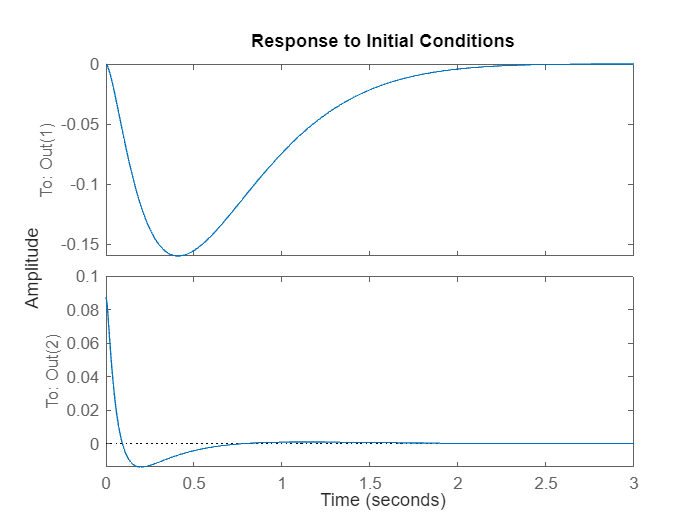

syslqr=ss(A_mat-B_mat*k,B_mat,C_mat,0);
x0 = [0; 5*pi/180; 0; 0];  % 5° disturbance
initial(syslqr, x0)

TF=tf(syslqr)

TF =
 
  From input to output...
               0.4867 s^2 - 1.383e-14 s - 715.5
   1:  ------------------------------------------------
       s^4 + 159 s^3 + 3233 s^2 + 1.392e04 s + 2.017e04
 
              3.65 s^2 - 6.711e-15 s - 6.227e-15
   2:  ------------------------------------------------
       s^4 + 159 s^3 + 3233 s^2 + 1.392e04 s + 2.017e04
 
Continuous-time transfer function.
Model Properties


## FeedBack Control

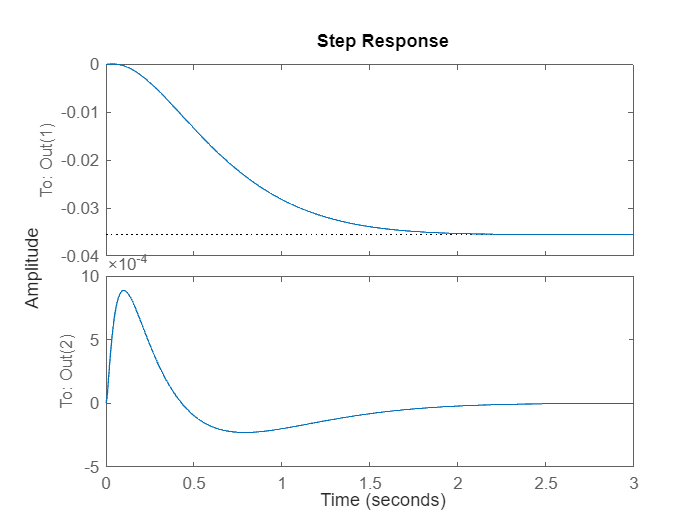

step(TF)

Acl = A_mat - B_mat*k;
eig(Acl)  

ans = 1.0e+02 *

  -1.3597 + 0.0000i
  -0.1782 + 0.0000i
  -0.0261 + 0.0123i
  -0.0261 - 0.0123i


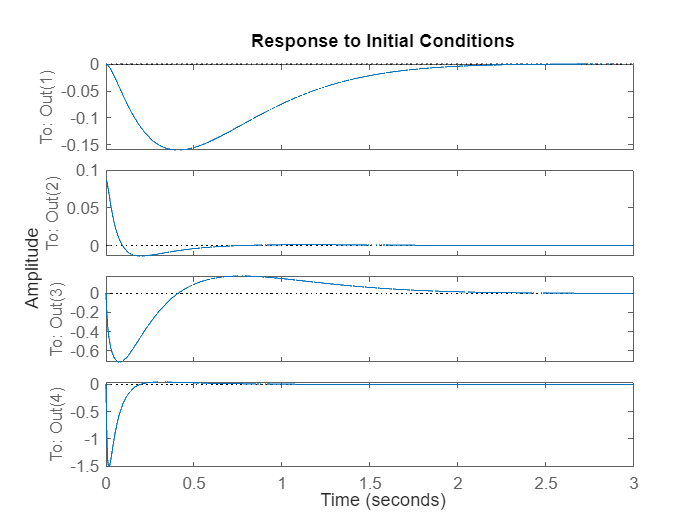


syscl = ss(Acl, B_mat, eye(4), 0);
x0 = [0; 5*pi/180; 0; 0];   % 5 deg from upright
initial(syscl, x0)